# Generalized linear-combination modeling

Written 2021-08-29, Georg Oeltzschner

In this script, I will keep an analysis workflow to generate appropriate data to develop and test my generalized linear-combination modeling framework.

**Prior to working in this script, check out the generalized-lcm branch in GitHub Desktop.**

clear;

% Add the path to the raw data
homePath = userpath;

% Add path to this notebook
pathData = strrep(homePath, ['Documents' filesep 'MATLAB'], ['OneDrive - Johns Hopkins' filesep '54_GeneralizedLCM']);
addpath(genpath(pathData));

% Add Osprey path
pathOsprey = fullfile(homePath, 'osprey');
addpath(genpath(pathOsprey));

Define the job file that we are going to want to use here.

jobFile = fullfile(pathOsprey, 'exampledata', 'sdat', 'UnEdited', 'jobSDAT.m');
diary logfile.txt;
[gLCM] = OspreyJob(jobFile, 0, '11');
[gLCM] = OspreyLoad(gLCM);
[gLCM] = OspreyProcess(gLCM);

## 1 Collecting everything we need for the fit

We'll try and set up a fit model here now. Let's collect everything that we need.

In parallel, I will develop the class `FitObject` along, which will hold the actual properties and methods that the FitObject will consist of.

% Initialize the conventional OspreyFit:
gLCM = osp_fitInitialise(gLCM);

% Grab data
dataToFit = gLCM.processed.metab{1};                       % HZ new naming conventions 

% Grab basis set
% Load the specified basis set or the user basis set file
basisSet = load(gLCM.opts.fit.basisSetFile);
basisSet = basisSet.BASIS;
basisSet = osp_recalculate_basis_specs(basisSet)            % HZ re-calculate specs

% 
basisSet = fit_sortBasisSet(basisSet);

## 2 Set up the FitObject

In this step, we'll initialize the FitObject by passing the data, basis set, and initial options.

% Create the spline basis functions for the given resolution, fit range,
% and knot spacing parameter.
opts.dkntmn             = 0.5; % minimum spacing between two neighboring spline knots
opts.optimDomain        = 'FD'; % do the least-squares optimization in the frequency domain
opts.optimSignalPart    = 'R'; % do the least-squares optimization over the real part of the spectrum
opts.optimFreqFitRange  = gLCM.opts.fit.range; % set the frequency-domain fit range to the fit range specified in the Osprey container

% Create an instance of the class
letsFitThis = FitObject(dataToFit, basisSet, opts);

Let's now decide which metabolites we want to exclude from the fit - by default, every signal in the basis set will be included in the fit.

% letsFitThis.excludeBasisFunctionFromFit({'Ala', 'bHB', 'bHG', 'Cit', 'Phenyl', 'Ser', 'Tyros', 'MMexp', 'MM37', 'MM37', 'MM38', 'MM40'}); 
letsFitThis.excludeBasisFunctionFromFit({'Ala','Asc','Asp','CrCH2','EtOH', 'bHB', 'bHG', 'Cit', 'GABA', 'GPC', 'Phenyl',...
                                          'GSH', 'Gln', 'Glu', 'Gly', 'H2O', 'mI', 'Lac', 'NAA', 'NAAG', 'PCh', 'PCr', 'PE', ...
                                          'sI', 'Tau', 'Ser', 'Tyros', 'MMexp','MM09', 'MM12', 'MM14','MM17', 'MM20', 'Lip09', ...
                                          'Lip13', 'Lip20', 'MM37', 'MM37', 'MM38', 'MM40'});
letsFitThis.plotBasisSet;

## 4 Fitting

### 4a Initial fitting

Once we have settled on our data, basis set, and fit options, we can start doing the actual fitting.

% Let's first start by initializing the fit parameters with a really coarse
% fit.
[ph0, gaussLB, lorentzLB, freqShift, metAmpl, baseAmpl] = letsFitThis.initFit;
letsFitThis.plotInitFit;

## 4b Complete fit

Now, we will do the actual fit.

letsFitThis.createModel;
letsFitThis.plotFit;

### 4.1 CRLB

## 5 Fitting water

Let's try and see whether we can fit water!

dataToFitWater = gLCM.processed.ref{1};

% Create the spline basis functions for the given resolution, fit range,
% and knot spacing parameter.
optsWater.dkntmn             = 2; % large knot spacing to force flat baseline
optsWater.optimDomain        = 'FD'; % do the least-squares optimization in the frequency domain
optsWater.optimSignalPart    = 'R'; % do the least-squares optimization over the real part of the spectrum
optsWater.optimFreqFitRange  = [0 8]; % big water fit range

% Create another instance of the class
letsFitWater = FitObject(dataToFitWater, basisSet, optsWater);

% Exclude all basis functions
letsFitWater.excludeBasisFunctionFromFit('all');
% Include only water
letsFitWater.includeBasisFunctionInFit('H2O');
% Run initial fit
[ph0W, gaussLBW, lorentzLBW, freqShiftW, metAmplW, baseAmplW] = letsFitWater.initFit;
% Plot initial fit
letsFitWater.plotInitFit;
letsFitWater.createModel;
letsFitWater.plotFit;

## 6 2D TE Series Test

load('/Volumes/Samsung/working/Shandong2/MSM/simulations/2D-TE/SNR_1/Dataset_Cr/jobSDAT.mat'); %Load simulations (change path accordingly)
DataToModel2D = MRSCont.processed.metab{2}; % Take a dataset
ModelInstructions = '/Volumes/Samsung/working/Shandong2/MSM/code/ModelProcedures/TE_Series_1Step_Spline_Cr.json'; %json description (change path accordingly)
% Look into the ModelInstructions for more details about the Physics Model
% as well as the description of the 2D model. You'll also have to change
% the path to the basissets and 2D model json! The decay function is
% described in the fitClass/dynamic-models folder.
[TESpline] = Osprey_gLCM(DataToModel2D,ModelInstructions); % Model data
% Print results now
TESpline{1, 1}.Model{1, 1}.parsOut.metAmplReparametrization.DecayAmpl
TESpline{1, 1}.Model{1, 1}.parsOut.metAmplReparametrization.DecayConstant

% To make this work you have to comment out the figure statement in the
% plotFit function
figure
tiledlayout(4,4)
for t= 1: 16
    nexttile
    TESpline{1}.plotFit(1,t);
end

## 7 Script for code review 

% Get example conventional MRS data
jobFile = fullfile(pathOsprey, 'exampledata', 'sdat', 'UnEdited', 'jobSDAT.m');
[MRSCont] = OspreyJob(jobFile, 0, '11');
[MRSCont] = OspreyLoad(MRSCont);
[MRSCont] = OspreyProcess(MRSCont);


### a) 1D no baseline regularization

% Run gLCM with unregularized baseline
[NoReg] = Osprey_gLCM(MRSCont.processed.metab{2},'which(fullfile(''Osprey_gLCM'',''fitClass'',''model-procedures'',''1Step_Spline_invivo.json''))');
NoReg{1}.plotFit(1)

% Run gLCM with unregularized baseline
[NoRegSC] = Osprey_gLCM(MRSCont.processed.metab{2},'which(fullfile(''Osprey_gLCM'',''fitClass'',''model-procedures'',''1Step_Spline_invivo_soft_constraint.json''))');
NoRegSC{1}.plotFit(1)


% Run gLCM with unregularized baseline and grouping MM lorentzian LB parameters
[NoRegGroupMM] = Osprey_gLCM(MRSCont.processed.metab{2},'which(fullfile(''Osprey_gLCM'',''fitClass'',''model-procedures'',''1Step_Spline_invivo_GroupingMM.json''))');
NoRegGroupMM{1}.plotFit(1)

### b) 1D with baseline regularization

% Run gLCM with regularized baseline with fixed Lambda
[Reg] = Osprey_gLCM(MRSCont.processed.metab{2},'which(fullfile(''Osprey_gLCM'',''fitClass'',''model-procedures'',''1Step_Spline_invivo_Reg.json''))');
Reg{1}.plotFit(1)


[RegSC] = Osprey_gLCM(MRSCont.processed.metab{2},'which(fullfile(''Osprey_gLCM'',''fitClass'',''model-procedures'',''1Step_Spline_invivo_Reg_soft_constraint.json''))');
RegSC{1}.plotFit(1)



% Run gLCM with regularized baseline with fixed Lambda and grouping MM
% lorentzian LB parameters
[RegGroupMM] = Osprey_gLCM(MRSCont.processed.metab{2},'which(fullfile(''Osprey_gLCM'',''fitClass'',''model-procedures'',''1Step_Spline_invivo_Reg_GroupingMM.json''))');
RegGroupMM{1}.plotFit(1)

### c) 1D with optimized baseline regularization

% Run gLCM with optimized baseline
[RegOpt] = Osprey_gLCM(MRSCont.processed.metab{2},'which(fullfile(''Osprey_gLCM'',''fitClass'',''model-procedures'',''3Step_Spline_invivo_Reg_Optim_Full.json''))');
RegOpt{1}.plotFit(1)
RegOpt{1}.plotFit(2)
RegOpt{1}.plotFit(3)


[RegOptSC] = Osprey_gLCM(MRSCont.processed.metab{1},'which(fullfile(''Osprey_gLCM'',''fitClass'',''model-procedures'',''3Step_Spline_invivo_Reg_Optim_Full_soft_constraint.json''))');
RegOptSC{1}.plotFit(1)
RegOptSC{1}.plotFit(2)
RegOptSC{1}.plotFit(3)


% Run gLCM with optimized baseline and smart parameter grouping
[RegOptGroup] = Osprey_gLCM(MRSCont.processed.metab{1},'which(fullfile(''Osprey_gLCM'',''fitClass'',''model-procedures'',''3Step_Spline_invivo_Reg_Optim_Full_GroupingPars.json''))');
RegOptGroup{1}.plotFit(1)
RegOptGroup{1}.plotFit(2)
RegOptGroup{1}.plotFit(3)


% Run gLCM with optimized baseline, smart parameter grouping, and soft
% constraints
[RegOptGroupSC] = Osprey_gLCM(MRSCont.processed.metab{2},'which(fullfile(''Osprey_gLCM'',''fitClass'',''model-procedures'',''3Step_Spline_invivo_Reg_Optim_Full_GroupingPars_soft_constraint.json''))',0,0,1);
RegOptGroupSC{1}.plotFit(1)
RegOptGroupSC{1}.plotFit(2)
RegOptGroupSC{1}.plotFit(3)


Running model procedure step 1. 


Resampling the basis set for you. 
Running model of dataset #1 of 1 


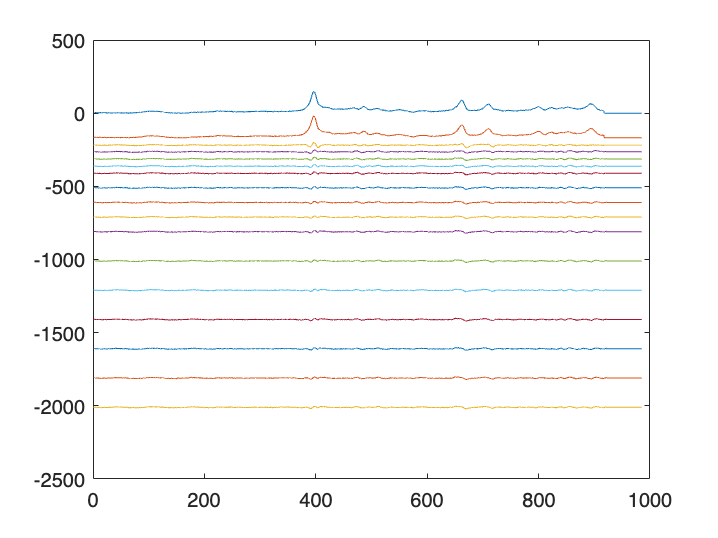

Running model procedure step 2. 
Running model of dataset #1 of 1 


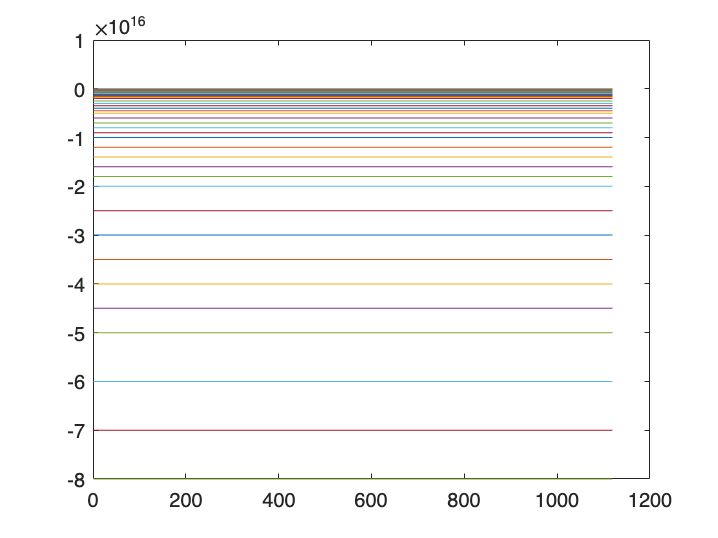


% Run gLCM with old Osprey-style model, smart parameter grouping, and soft
% constraints
[OldOsprey] = Osprey_gLCM(MRSCont.processed.metab{2},'which(fullfile(''Osprey_gLCM'',''fitClass'',''model-procedures'',''2Step_Spline_invivo_GroupingPars_soft_constraint.json''))',0,0,1);

Current plot held


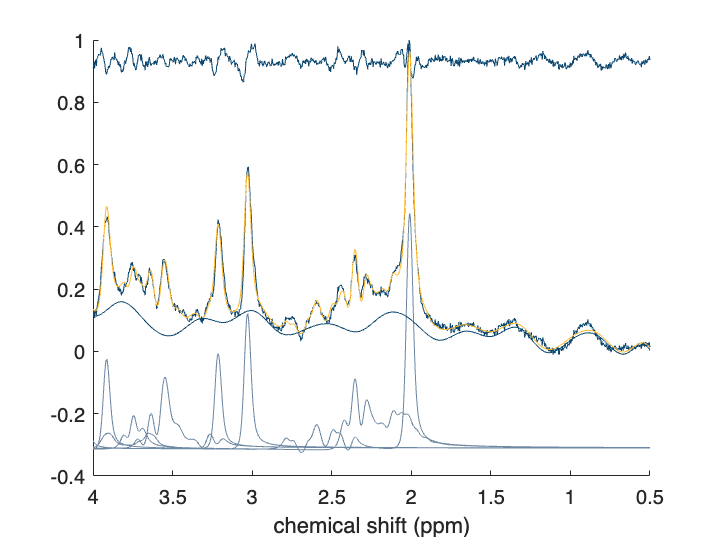

OldOsprey{1}.plotFit(1)

Current plot held


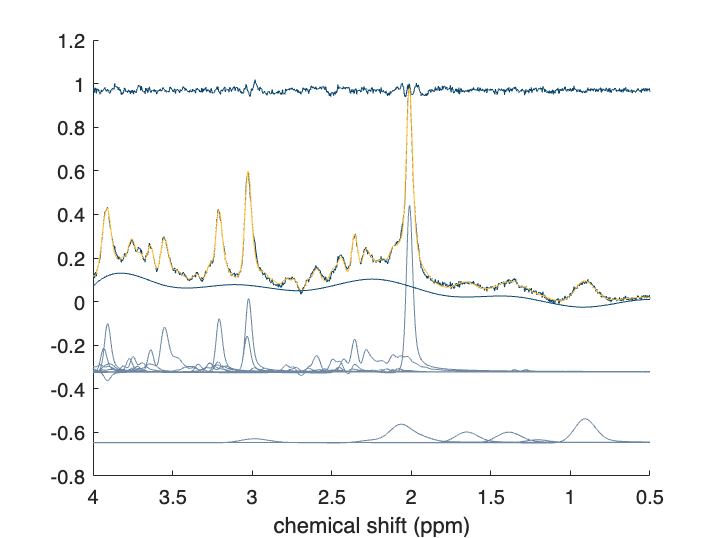

OldOsprey{1}.plotFit(2)

### d) 2D TE Series 

TESeries = OspreyJob('/Volumes/Samsung/working/Shandong2/MSM/code/ProgressReport/job_PCC_TE_GABA_GSH.m',0,'11');
TESeries = OspreyLoad(TESeries);
TESeries = OspreyProcess(TESeries);
[TEs] = Osprey_gLCM(TESeries.processed.metab{1},'/Volumes/Samsung/working/Shandong2/MSM/code/ProgressReport/ModelProcedures/TE_Series_1Step_Spline_ExpMM_PRESS.json');